# T1 and T2 signals across time

This script plots more about the time course of T1 and T2 weighted signals using realistic parameters.

We can plot the signals across the time-course and simulate signal's behaviors in terms of differential equations.

We reproduce a figure from J. Hornak's book: ([https://www.cis.rit.edu/htbooks/mri/chap-10/chap-10-h5.htm](https://www.cis.rit.edu/htbooks/mri/chap-10/chap-10-h5.htm)). 

This part of the tutorial can help you learn about 

- a link between exponential functions to differential equations 

- why we need some equilibrating cycles before the image acquisition.

## Set up the parameters

TR = 500;
total_time = 8600; %stop time (ms)
dt = 1;            % time delta (ms)
timeSteps = linspace(0,dt,total_time);

Mz = zeros(size(timeSteps));   %longitudinal magnetization
Mxy = Mz;                      %transverse magnetization
Mz(1) = 1;     % Set to 1 (should be proton density of each voxel?)
RFtime = 100;  % This is when the RF pulse??

% In seconds
gT1 = 1.2;  gT2 = 0.110; gT2star = 0.11;  
wT1 = 0.8;  wT2 = 0.080; wT2star = 0.08; 
cT1 = 4.27; cT2star = 1.58;

## Evaluate gray matter signal

for t = 1:dt:total_time
    
    % Longitudinal magnitization
    Mz(t+1) =  Mz(t) + dt*(1-Mz(t))/(gT1*1000);
    
    %Transverse magnetization
    Mxy(t+1) = Mxy(t) - dt*Mxy(t)/(gT2*1000);

    % apply RF pulse (90° pulse)
    if t>= RFtime
        Mxy(t+1) = Mz(t+1);
        % Flip longitudinal magnetization to transverse longitudinal
        Mz(t+1) = 0; % reset longitudinal magnetization
        RFtime = RFtime+TR; % account for the next RF time
    end
end


## Why we remove a few early time measurements

It takes a few cycles for the signal to reach the equilibrium state.  Thus, we need some equilibrating cycles in the beginning of every image acquisition.

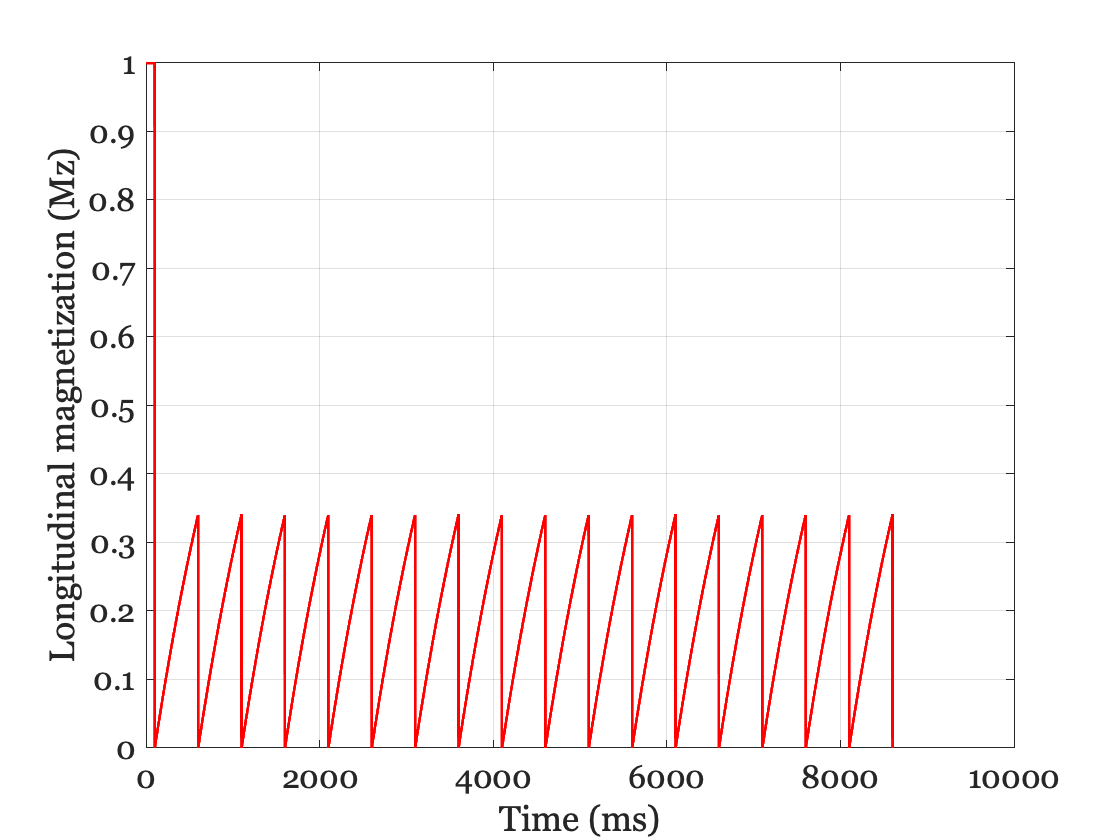

figure;
plot(Mz,'linewidth',1.5); grid on; hold on;
ylabel('Longitudinal magnetization (Mz)'); xlabel('Time (ms)');

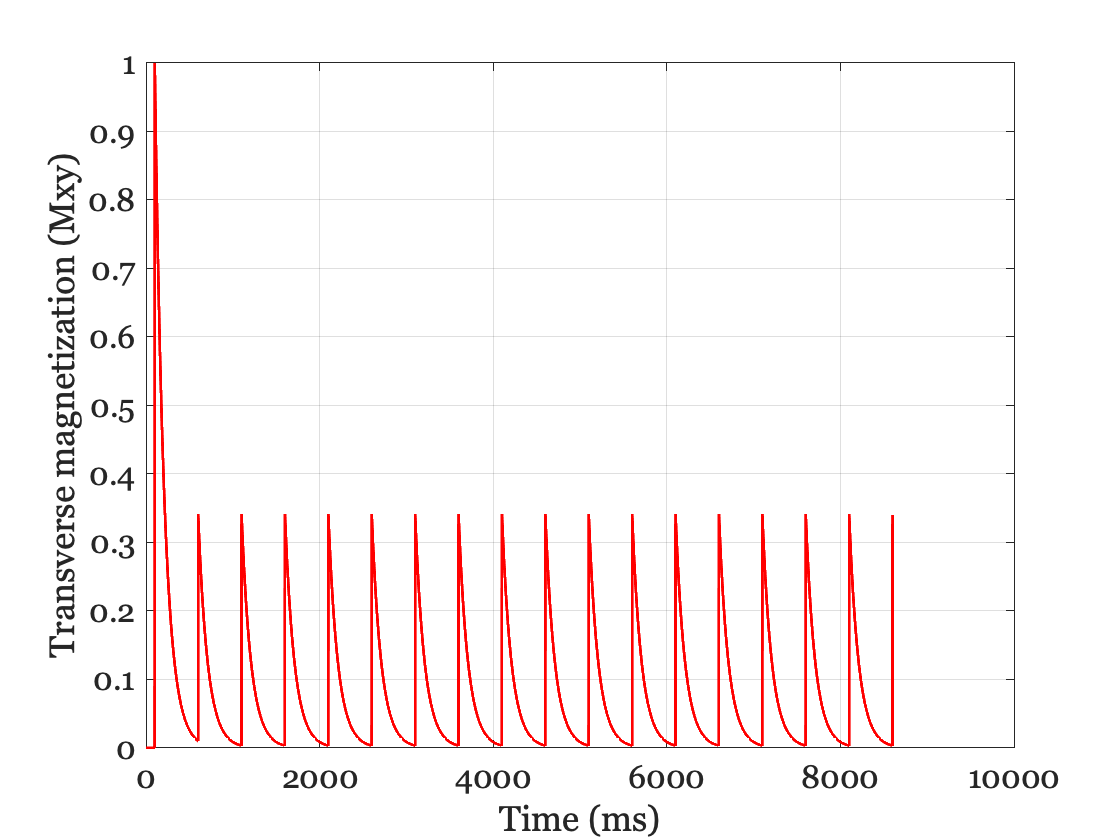


figure;
plot(Mxy,'linewidth',1.5); grid on; hold on;
xlabel('Time (ms)'); ylabel('Transverse magnetization (Mxy)');

## Evaluate white matter signal

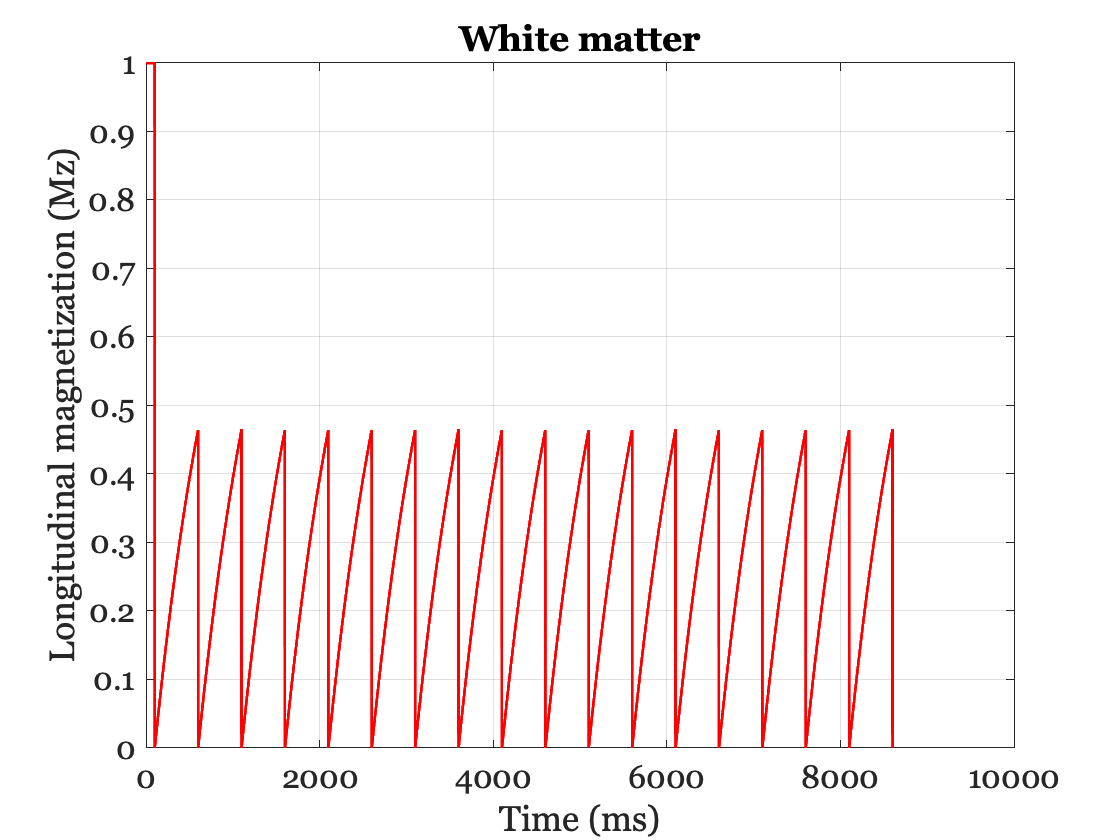

Mz = zeros(size(timeSteps));   %longitudinal magnetization
Mxy = Mz;  %transverse magnetization
Mz(1) = 1; % set first value to be 1 (should be proton density of each voxel?)
RFtime = 100;  %This is when the RF


for t = 1:dt:total_time
    
    % Longitudinal magnitization
    Mz(t+1) =  Mz(t) + dt*(1-Mz(t))/(wT1*1000);
    
    %Transverse magnetization
    Mxy(t+1) = Mxy(t) - dt*Mxy(t)/(wT2*1000);

    % apply RF pulse (90° pulse)
    if t>= RFtime
        Mxy(t+1) = Mz(t+1);
        % Flip longitudinal magnetization to transverse longitudinal
        Mz(t+1) = 0; % reset longitudinal magnetization
        RFtime = RFtime+TR; % account for the next RF time
    end
end

figure;
plot(Mz,'linewidth',1.5); grid on;
ylabel('Longitudinal magnetization (Mz)'); xlabel('Time (ms)');
title('White matter')

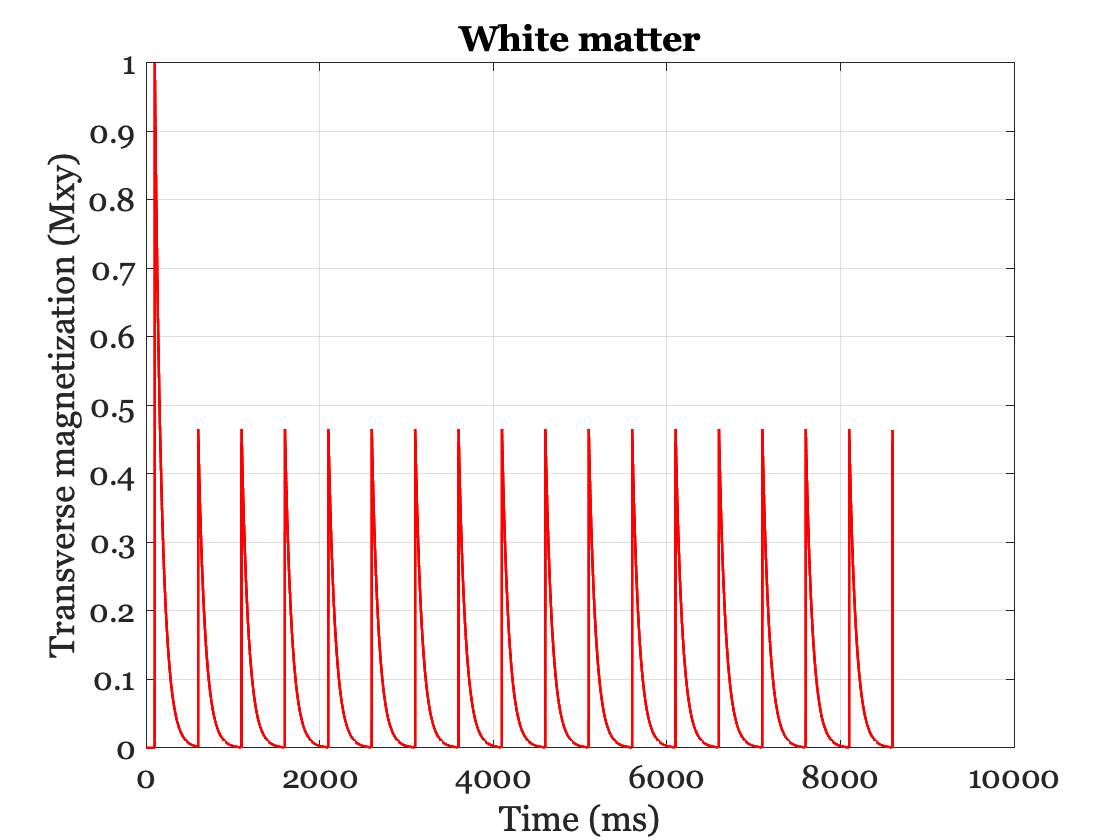


figure;
plot(Mxy,'linewidth',1.5); grid on;
xlabel('Time (ms)'); ylabel('Transverse magnetization (Mxy)');
title('White matter')